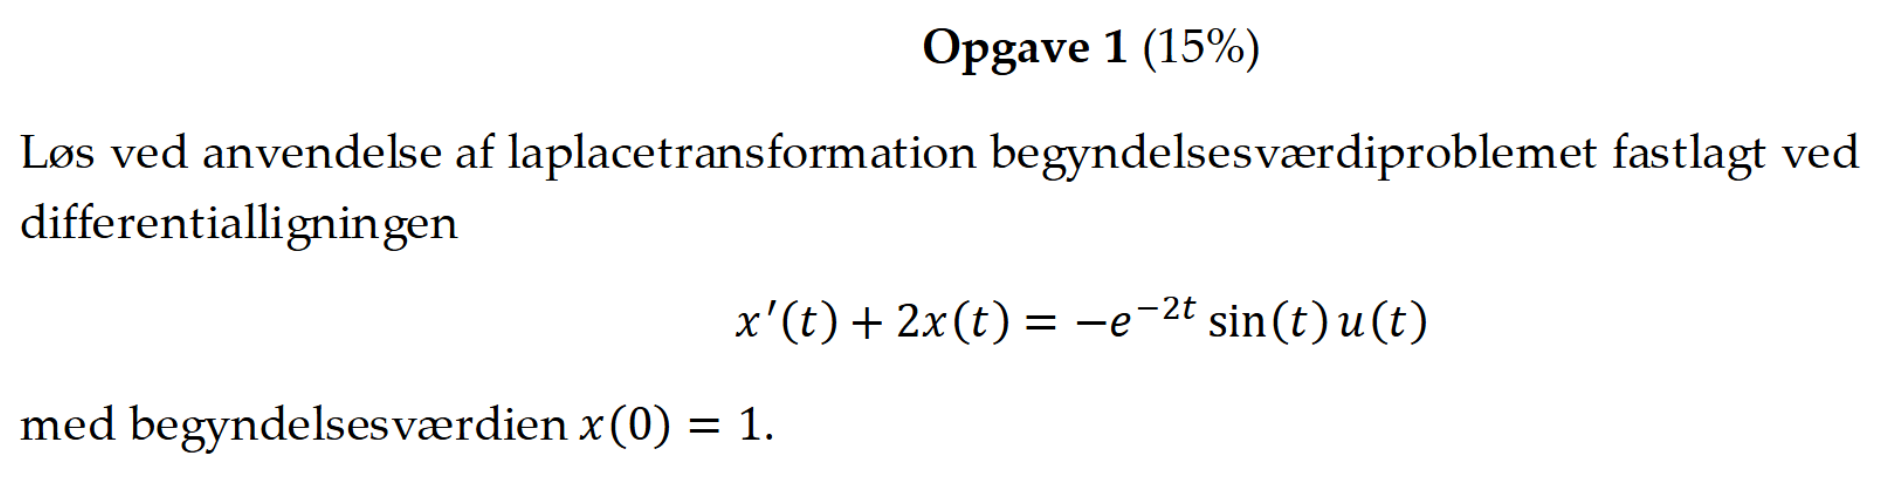

% Opsæt symbolske variable
syms t s;

% Definer differentialligningen: x'(t) + 2x(t) = -e^(-2t)*sin(t)*u(t)
% Differentialligning på standardform: a_n*y^(n) + ... + a_1*y' + a_0*y = f(t)
a = [1, 2];  % Koefficienter [a_1, a_0] for x'(t) + 2x(t)
b = [-1];    % Koefficient for højresiden

% Begyndelsesværdi
x0 = 1;      % x(0) = 1

% Højreside-funktion
f_t = exp(-2*t)*sin(t);

% Løs differentialligningen ved hjælp af biblioteket
[num, den] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);
[h_t, forklaringsOutput] = ElektroMatBibTrinvis.beregnUdgangssignalMedForklaring(tf(num, den), laplace(f_t, t, s), s, t);

% Tilføj begyndelsesværdien til den homogene løsning
x_t = h_t + x0*exp(-2*t);

disp('Løsningen på differentialligningen er:');
disp(x_t);

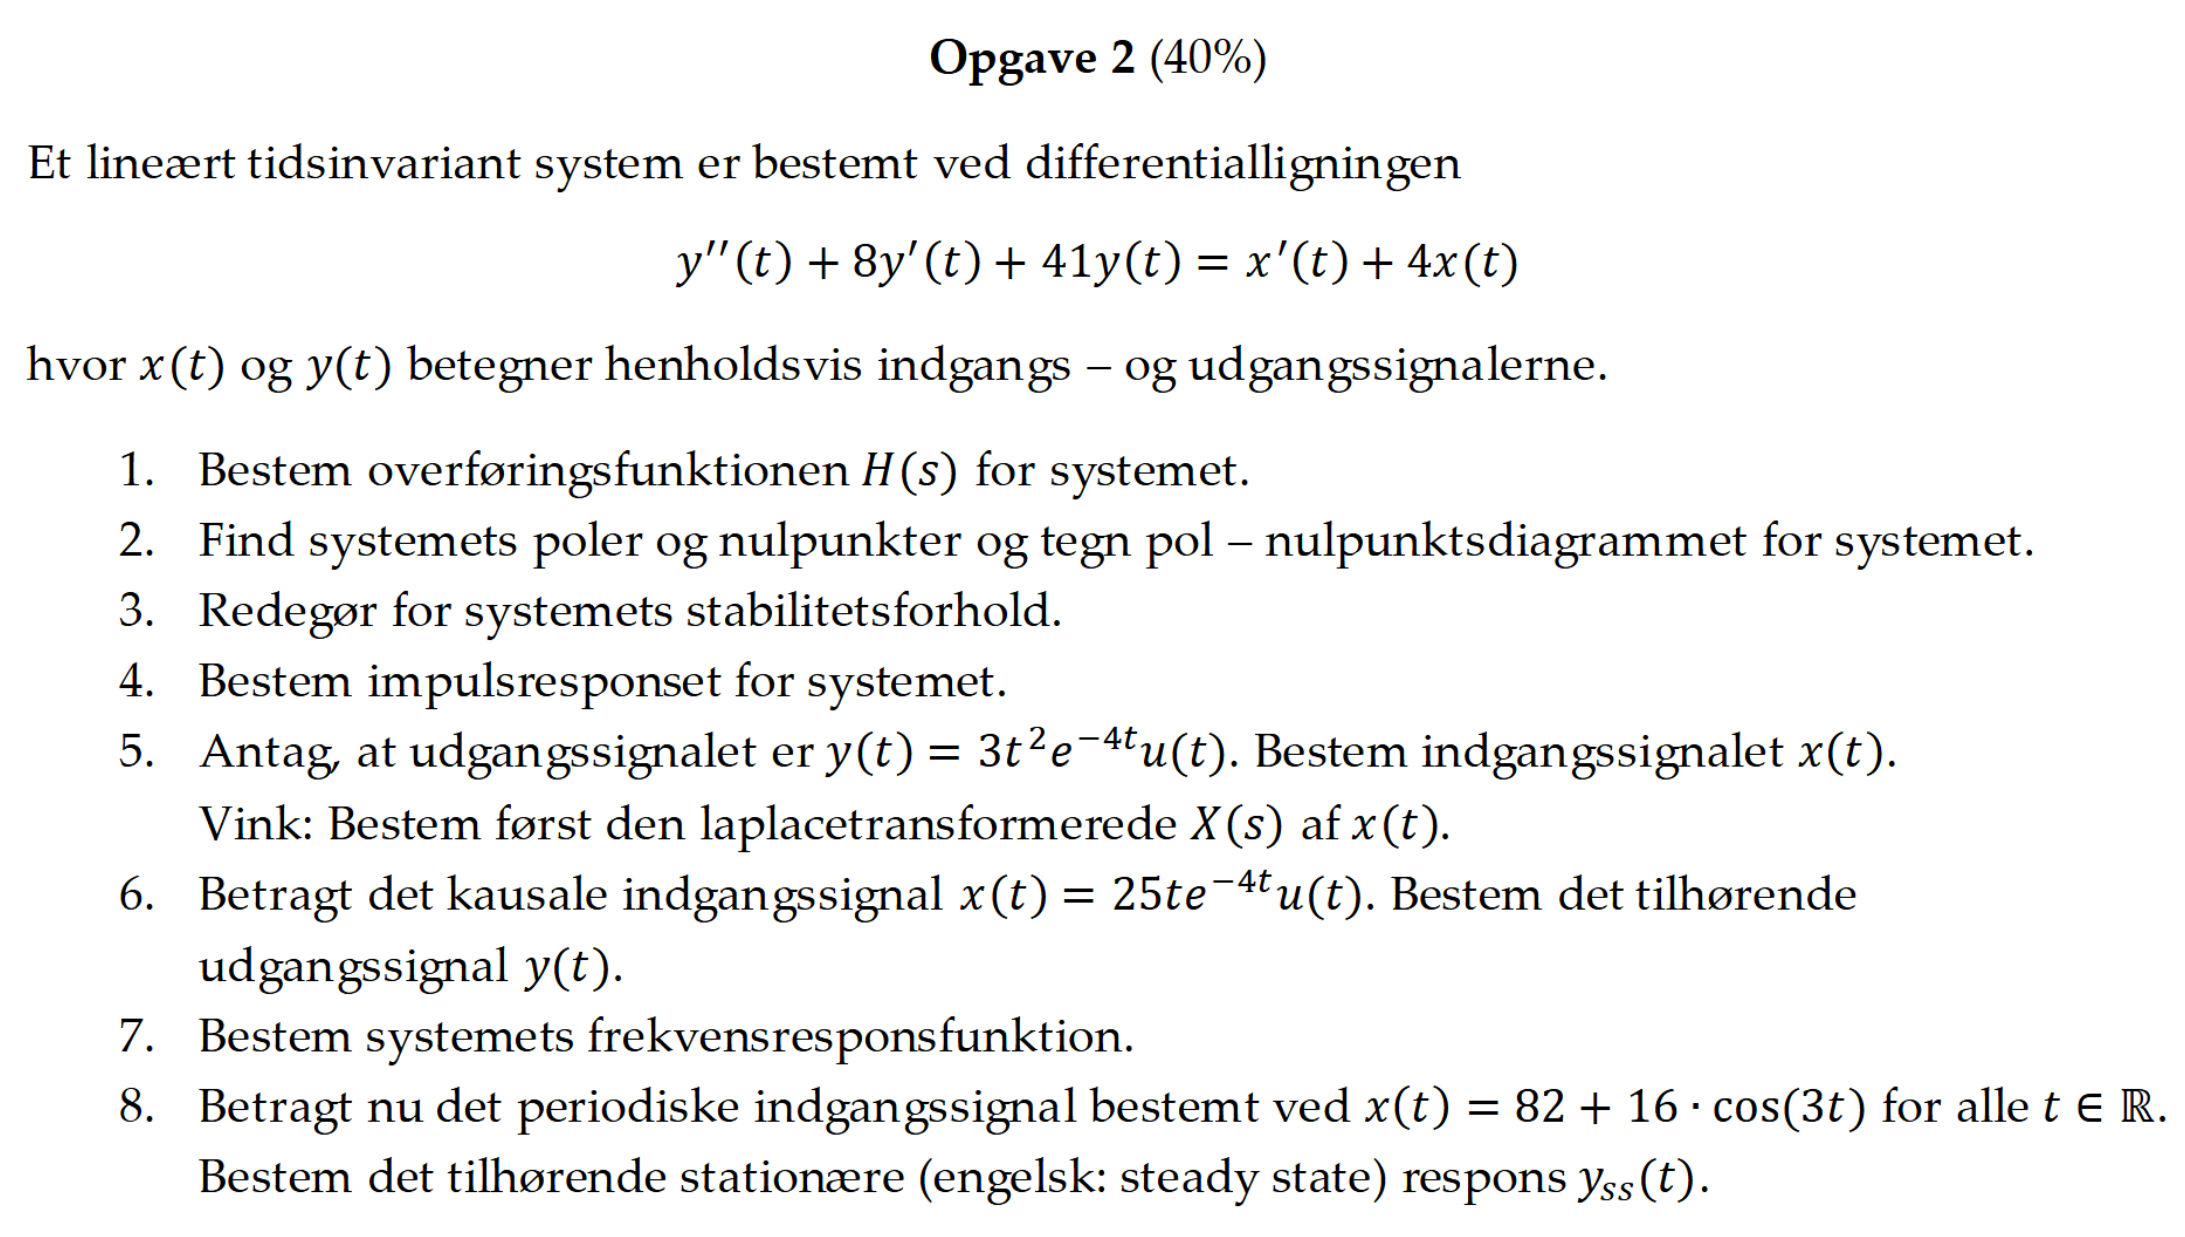

### 1. Bestem overføringsfunktionen 𝐻(𝑠) for systemet.

disp('Opgave 1: Bestem overføringsfunktionen 𝐻(𝑠) for systemet.');

% Definerer koefficienterne for output og input
a = [1, 8, 41]; % Koefficienter for y'', y', y
b = [1, 4];     % Koefficienter for x', x

% Beregn overføringsfunktionen
[num, den, forklaring] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

% Vis resultatet symbolsk
syms s;
H(s) = poly2sym(num, s) / poly2sym(den, s)

### 2. Find systemets poler og nulpunkter og tegn pol – nulpunktsdiagrammet for systemet

disp('Opgave 2: Find systemets poler og nulpunkter og tegn pol – nulpunktsdiagrammet for systemet');

% Beregn poler og nuller
poler = roots(den);
nuller = roots(num);

% Vis poler og nuller
disp('Systemets poler:');
disp(poler);
disp('Systemets nuller:');
disp(nuller);

% Tegn pol-nulpunktsdiagram
figure;
pzmap(tf(num, den));
grid on;
title('Pol-nulpunktsdiagram');

### 3. Redegør for systemets stabilitetsforhold

disp('Opgave 3: Redegør for systemets stabilitetsforhold');

% Analyser differentialligningen for at undersøge stabilitet
forklaringsOutput = ElektroMatBibTrinvis.analyserDifferentialligningMedForklaring(a);

% Tjek polers placering for at bestemme stabilitetstype
if any(real(poler) > 0)
    disp('Systemet er USTABILT da mindst én pol har positiv realdel.');
elseif any(abs(real(poler)) < 1e-10)  % Tjek for poler på den imaginære akse (med numerisk tolerance)
    disp('Systemet er MARGINALT STABILT da mindst én pol ligger på den imaginære akse.');
else
    disp('Systemet er ASYMPTOTISK STABILT da alle poler har negativ realdel.');
end

% Vis polernes placering i det komplekse plan for detaljeret stabilitetsanalyse
disp('Poler:');
for i = 1:length(poler)
    disp(['Pol ' num2str(i) ': ' num2str(poler(i))]);
end

### 4. Bestem impulsresponset for systemet.

disp('Opgave 4: Bestem impulsresponset for systemet.');

% Beregn systemets impulsrespons
[t, y, impulsForklaring] = ElektroMatBibTrinvis.beregnStepresponsMedForklaring(num, den, [0, 10]);

% Du kan også beregne impulsresponset ved invers Laplace-transformation af H(s)
syms s t;
H_s_sym = poly2sym(num, s) / poly2sym(den, s);
[h_t, invLapForklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s_sym, s, t);

### 5. Antag, at udgangssignalet er $y\left(\textrm{𝑡}\right)=3{\textrm{𝑡}}^2 {\textrm{𝑒}}^{-4t} \textrm{𝑢}\left(\textrm{𝑡}\right)$. Bestem indgangssignalet $x\left(t\right)$. Vink: Bestem først den laplacetransformerede $X\left(S\right)$ af $x\left(t\right)$.

disp('Opgave 5: Antag, at udgangssignalet er . Bestem indgangssignalet . Vink: Bestem først den laplacetransformerede  af .');

% Definér udgangssignalet
syms t s;
y_t = 3*t^2*exp(-4*t);

% Beregn Laplace-transformationen af y(t)
[Y_s, lapForklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(y_t, t, s);

% Find H(s) symbolsk
H_s_sym = poly2sym(num, s) / poly2sym(den, s);

% Beregn X(s) = Y(s)/H(s)
X_s = Y_s / H_s_sym;
X_s = simplify(X_s);

% Find x(t) ved invers Laplace-transformation
[x_t, invLapForklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(X_s, s, t);

### 6. Betragt det kausale indgangssignal $x\left(t\right)=25{\textrm{te}}^{-4t} u\left(t\right)$. Bestem det tilhørende udgangssignal $y\left(t\right)$.

### 7. Bestem systemets frekvensresponsfunktion.

### 8. Betragt nu det periodiske indgangssignal bestemt ved $x\left(t\right)=82+16*\cos \left(3t\right)$ for alle $\textrm{𝑡}\in \mathbb{R}$. Bestem det tilhørende stationære (engelsk: steady state) respons $y_{\textrm{ss}} \left(t\right)$.

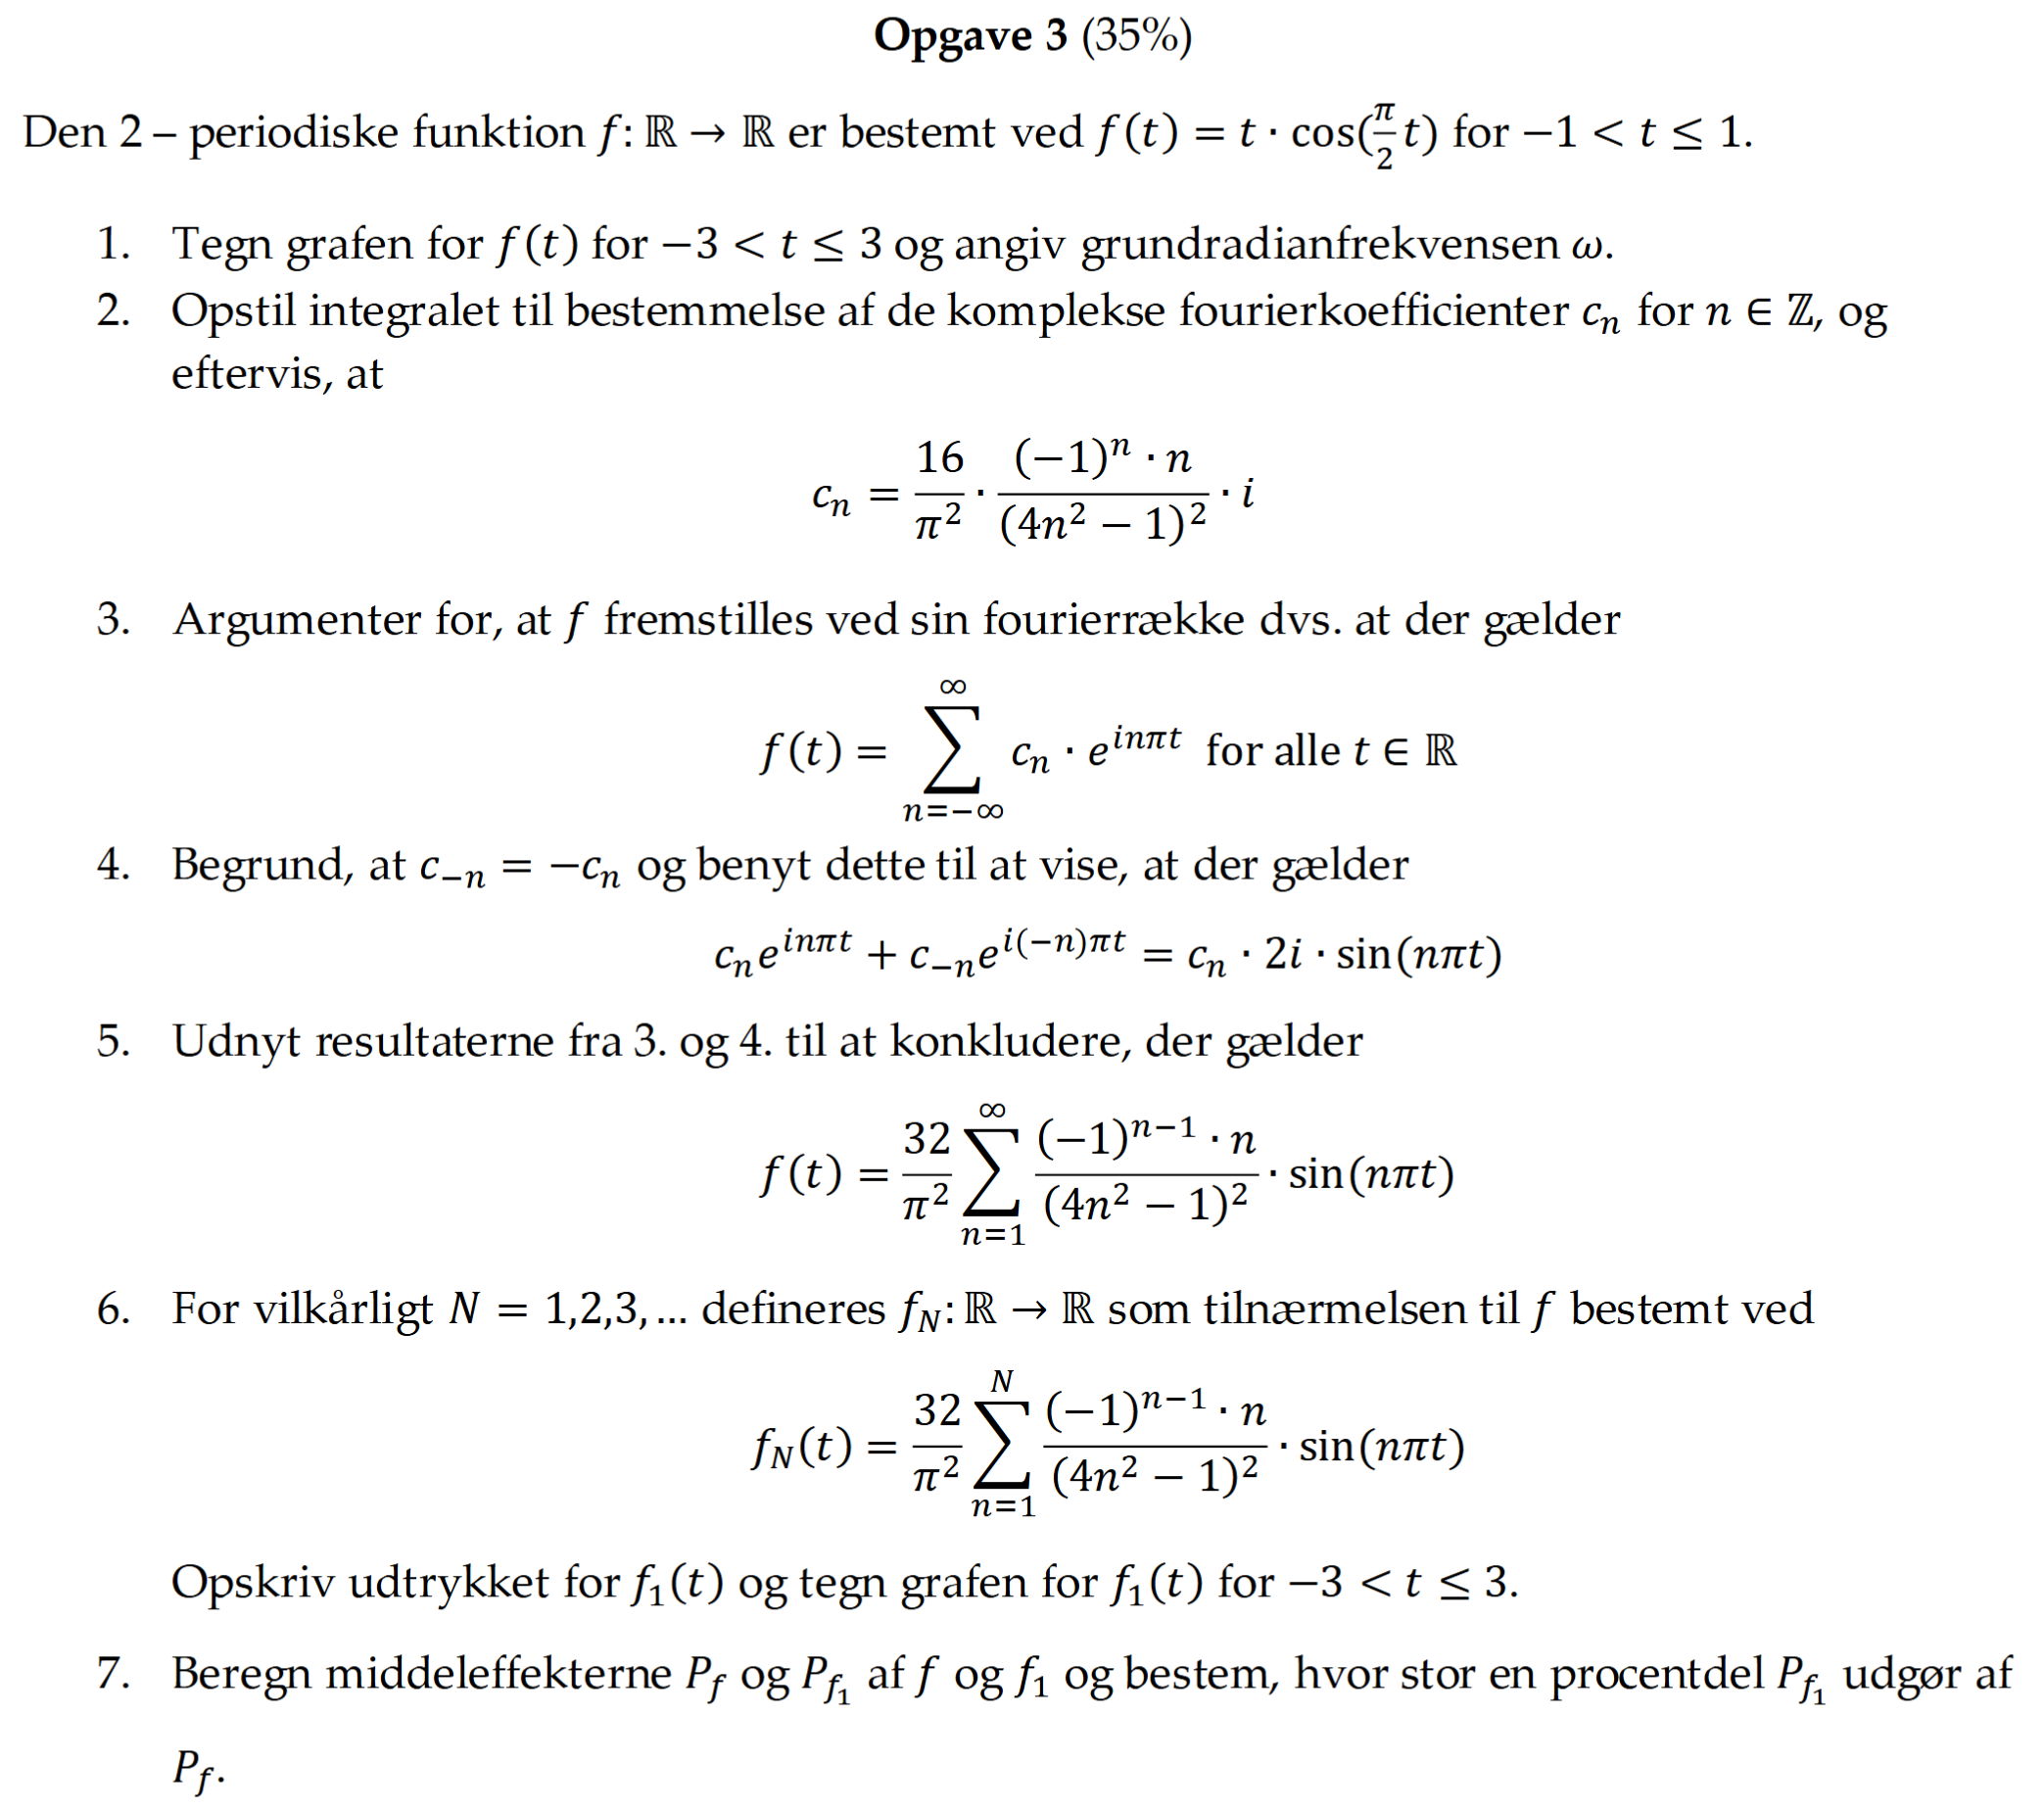

1. Tegn grafen for 𝑓(𝑡) for −3 < 𝑡 ≤ 3 og angiv grundradianfrekvensen 𝜔.

2. Opstil integralet til bestemmelse af de komplekse fourierkoefficienter 𝑐𝑛 for 𝑛 ∈ ℤ, og eftervis, at $c_n =\frac{16}{\pi^2 }=\frac{{\left(-1\right)}^n *n}{{\left(4n^2 -1\right)}^2 }*i$

3. Argumenter for, at 𝑓 fremstilles ved sin fourierrække dvs. at der gælder

4.